# **FOURIER TRANSFORM ANALYSIS**

**Initially an analysis of a stationary signal will be carried out and subsequently an analysis of a non-stationary signal to highlight the relative criticalities of the analysis. Finally, a comparison will be made to highlight the problems resulting from the Fourier transform analysis of a non-stationary signal (chirp).**

clear; close all; clc;

## **Stationary signal analysis**

Specify the parameters of a signal with a sampling frequency of 1 kHz and a signal duration of 1.5 seconds.

fs = 1000;            % Sampling frequency                    
ts = 1/fs;            % Sampling period       
l = 1500;             % Length of signal
t = (0:l-1)*ts;       % Time vector
f = fs*(0:(l/2))/l;  % Scaling

Form a signal containing a 50 Hz sinusoid of amplitude 0.7 and a 120 Hz sinusoid of amplitude 1.

frequencies = [10, 50, 80, 120];
stationary_signal = 0.9*sin(2*pi*frequencies(1)*t) + sin(2*pi*frequencies(2)*t) ...
                  + 0.4*sin(2*pi*frequencies(3)*t) + 1.2*sin(2*pi*frequencies(4)*t);

Compute FT

X_stationary_signal = fft(stationary_signal);

Signal and FT plot

figure;
signal_slider =250;
subplot(211), plot(1000*t(1:signal_slider), stationary_signal(1:signal_slider));
title('Stationary signal');
xlabel('t'), ylabel('x(t)');

This step is calculating the normalized Fourier transform magnitude by dividing each complex value in X_stationary_signal by the signal length l and taking the absolute value to get the magnitude.

mag_non_stationary_signal = abs( X_stationary_signal / l );

Here, we're only taking the positive half of the magnitude of the Fourier transform. The reason is that the Fourier transform has symmetry about the center, so the negative half is a duplicate of the positive half.

half_mag_non_stationary_signal = mag_non_stationary_signal(1:l/2+1);

Plot of the spectrum

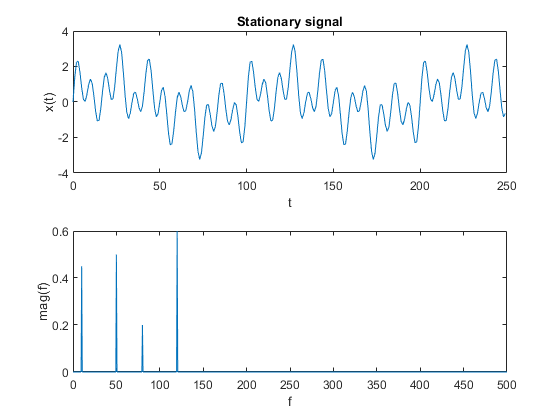

subplot(212), plot(f, half_mag_non_stationary_signal);
xlabel('f'), ylabel('mag(f)');

## Non-stationary signal analysis

Corrupt the signal with zero-mean white noise

non_stationary_signal = stationary_signal + 2*randn(size(t));

Plot the noisy signal in the time domain. It is difficult to identify the frequency components by looking at the signal x(t).

figure;
signal_slider =350;
subplot(211), plot(1000*t(1:signal_slider),non_stationary_signal(1:signal_slider));
title('Non stationary signal');
xlabel('t'), ylabel('x(t)');

Compute the Fourier transform of the signal.

X_non_stationary_signal = fft(non_stationary_signal);

Compute the two-sided spectrum P2. Then compute the single-sided spectrum P1 based on P2 and the even-valued signal length L.

mag_non_stationary_signal = abs(X_non_stationary_signal/l);
half_mag_non_stationary_signal = mag_non_stationary_signal(1:l/2+1);
half_mag_non_stationary_signal(2:end-1) = 2*half_mag_non_stationary_signal(2:end-1);

Define the frequency domain f and plot the single-sided amplitude spectrum P1. The amplitudes are not exactly at 0.7 and 1, as expected, because of the added noise.

On average, longer signals produce better frequency approximations.

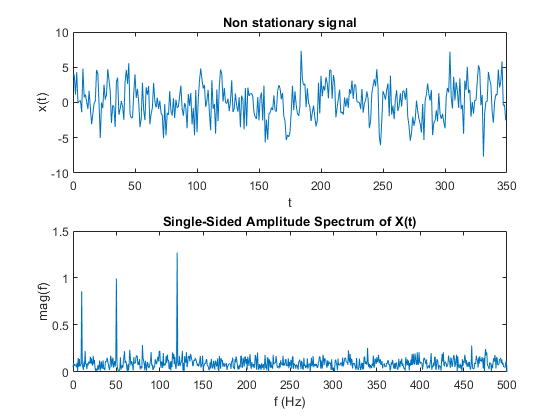

subplot(212), plot(f, half_mag_non_stationary_signal);
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)'), ylabel('mag(f)');

Indeed, it can be noted that in the case of a stationary signal, the spectrum analysis is more difficult due to this additional "noise". Indeed, in this case, it is possible to confuse the small amplitude frequency components with the noise surrounding them. Therefore, for non-stationary signals it is recommended to use a different transformation that allows a more accurate analysis of the spectrum.